## FOC: Compensation Control Scheme

When it comes to the design ot the field-oriented current control loop, the most common control structures make use of two simple PI-regulators. This is a good choice, because they are easy to implement and -correcty parameterized-, they fit our demands for the control system (see: Is PID control superior to PI-control?) 

Many application notes and control unit manufacturers are recommending to parameterize the PI-controller gains by the use of the compensation control scheme, a special case of the optimum magnitude criteria. The calcultion is based on the fundamental electrical equations in the dq-reference frame:


$$u_d = R_s \, i_d + L_d\,\frac{d i_d}{d t} - L_q\,\Omega_{el}\,i_q$$



$$u_q = R_s \, i_q + L_q\,\frac{d i_q}{d t} + L_d\,\Omega_{el}\,i_d + \Omega_{el}\,\Psi_m$$


Now, let's assume that we feedforward-compensated the coupling terms correctly and there are no distrubance terms (caused by harmonics, cross-couplings, interlocking-time...).  This simplifies our equations to:


$$u_d = R_s \, i_d + L_d\,\frac{d i_d}{d t} $$



$$u_q = R_s \, i_q + L_q\,\frac{d i_q}{d t}$$


It can be seen that the equation for both axis have the same structure, so as further example, we'll stick with the equation for the d-axis. The Laplace tramsform of the feedfordward-compensated d-axis equation leeds us to:


$$G_p(s) = \frac{1}{L_d\,s+R_s} = \frac{R_s^{-1}}{\frac{L_d}{R_s}\,s+1}$$



$$G_r(s)=k_p+\frac{k_i}{s}$$



$$G_w(s)=$$


That's a simple first-order lag with a steady state gain of G = 1/R_s and a time constant of tau = L_d/R_s. Using the compensation control scheme, the control gains are given as


$$k_p = \frac{L_d}{T_w}=2\,\pi\,f_w\,L_d\qquad k_i = \frac{R_s}{T_w} = 2\,\pi\,f_w\,R_s$$
 

whereas T_w is our desired time-constant for the closed loop system. Now, we can adjust the bandwidth of the closed loop system by adjusting T_w. But is there a catch?

### Case 1: Low Bandwidth / Slow Control

Let's analyze the reference step response of our closed loop system in the time domain. If we use the equations above to design a PI-regulator choosing f_w = 1/(2*pi*T_w) = 400 Hz as our desired closed loop bandwidth, we get the following reference step response

/Bild 1

This looks good, doesn't it? But keep in mind that this step response is only archiveble with a continous controller. And as long we don't want to realize our control algorithm including all compensations and transformations with operational amplifiers, we have to discretize our control algorithm to be able to implement it on our MCU or DSP. 

So if we use a suitable discretization method (in this example: biliniar transformation / tustin, sample time: 20kHz) and don't mess around with any fancy online integration methods, we get the following step response:

/Bild 2 

Still not too bad, but cerainly different. The compensation isn't exact anymore and as a consequence, our closed loop dynamics changed:

Continuous                  Discrete

Gain Margin: Inf     18

Phase Margin: 90 degree    79 degree

But there is another cause for the deviation: The control loop deadtime, not to be confused with the deadtime used for the inverter shoot-through protection, which we call interlocking time. If we analze our step response using zero-order hold for our discrete plant model, the discretization assumes that we output the new control signal exactly at the time we read our inputs. This isn't possible in practice as our calculation takes some time and the new counter compare values for the inverter are set. This lag is taken in consideration in the plot above.

Overall, we're seeing not the bandwidth we intended to set our closed loop to. Even if stability isn't in danger, it's not the dynamic reponse we desigend for. 

### Case 1: High Bandwidth / Fast Control

But what happens if the bandwidth above isn't sufficient for us because we're desiging a high performance application. Now, we want our closed loop bandwidth to be at f_w = 2000 Hz. 

/Bild

As we see, the continous compensation controller does his job flawlessly, quite contrary to the discrete implementation. The resulting dynamics differ significantly and as our satbility margins show, even the stabilibty of the control system is in danger.

Continuous                  Discrete

Gain Margin: Inf     4

Phase Margin: 90 degree    35 degree

The control gains given by the compensation control scheme are calculated for the coninuous case, and as we're approaching the nyquist frequency, the differences are starting to rise heavily. To be specific, the intended compensation controller fail to compenssate the plant dynamics.

But there is a two staged solution: At first, we differ from the continuous compensation control scheme and compute the parameters for the discrete case directly. These calculations are a bit more complex, but they only differ the k_p and k_i  gains so there is no increased computation on the MCU or DSP. 

Secondly, we have to compensate the dead-time using an optimal observer. These two actions "restore" our inteneded compensation scheme:

\Bild 

As for validation, we implemented both algorithms on our prototyping control unit and measured the step response for i_d_ref = 10A. Both, the consequences of the use of the bla in control system and the effictiveness of the direct-discrete calculations + dead time compensation can be seen easily.

t_plot = 5e-3;

f_w = 400;
T_w = 1/(2*pi*f_w);

L_d = 25e-6;
R_s = 50e-3;
G_p = tf(1/R_s,[L_d/R_s 1]);

k_p = L_d/T_w;
k_i = R_s/T_w;
G_r = k_p + tf(k_i,[1 0]);

F_o = G_r*G_p;
G_w = feedback(G_r*G_p,1);

[data_c, time_c] = step(G_w,t_plot);

Bw = bandwidth(G_w);
Bw = Bw/(2*pi);

disp(Bw)

  399.0513



[Gm,Pm,~,~] = margin(F_o);
Gm = 20*log10(Gm);
disp(Gm)

   Inf



disp(Pm)

    90



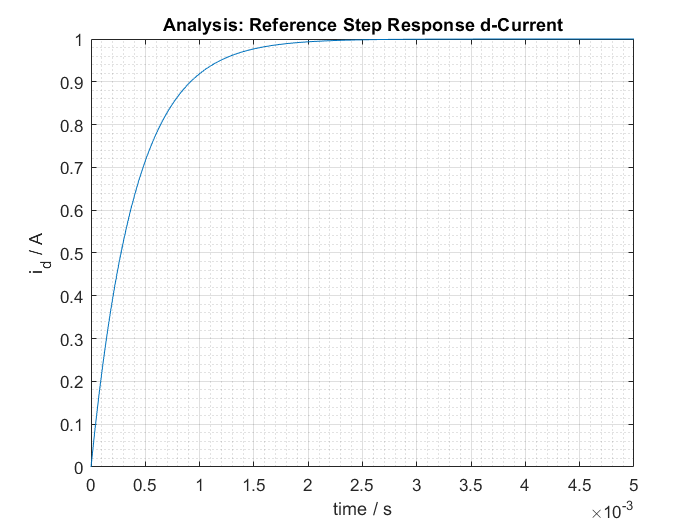

figure;
plot(time_c,data_c);
grid on
title('Analysis: Reference Step Response d-Current')
xlabel('time / s')
ylabel('i_d / A')
grid minor 

% figure;
% pzmap(G_w)
t_s = 1/20000;

dG_p = c2d(G_p,t_s,'zoh');
dG_r = c2d(G_r,t_s,'tustin');
dG_del = tf(1,[1 0],t_s);
dF_o = dG_r*dG_del*dG_p;
dG_w = feedback(dG_r*dG_del*dG_p,1);

[data_d, time_d] = step(dG_w,t_plot);


Bw = bandwidth(dG_w);
Bw = Bw/(2*pi);

disp(Bw)

  504.6670



[Gm,Pm,~,~] = margin(dF_o);
Gm = 20*log10(Gm);
disp(Gm)

   18.0226



disp(Pm)

   79.1751



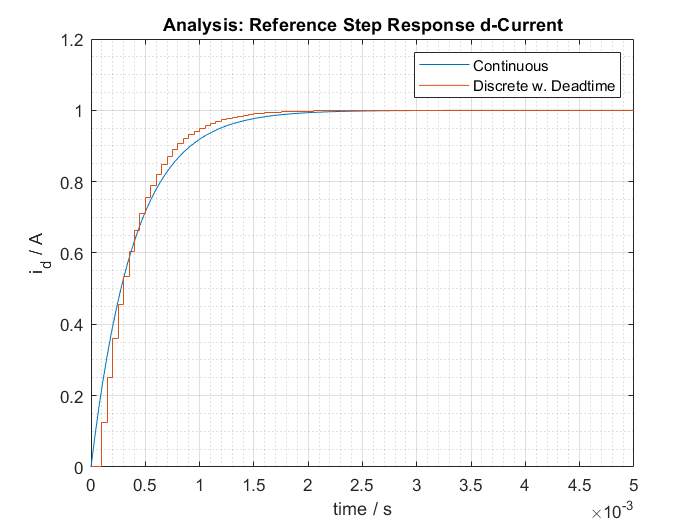




figure;
plot(time_c,data_c);
hold all
stairs(time_d,data_d);
grid on
legend('Continuous','Discrete w. Deadtime')
title('Analysis: Reference Step Response d-Current')
xlabel('time / s')
ylabel('i_d / A')
grid minor 

### Fall 2 Hohe Bandbreite

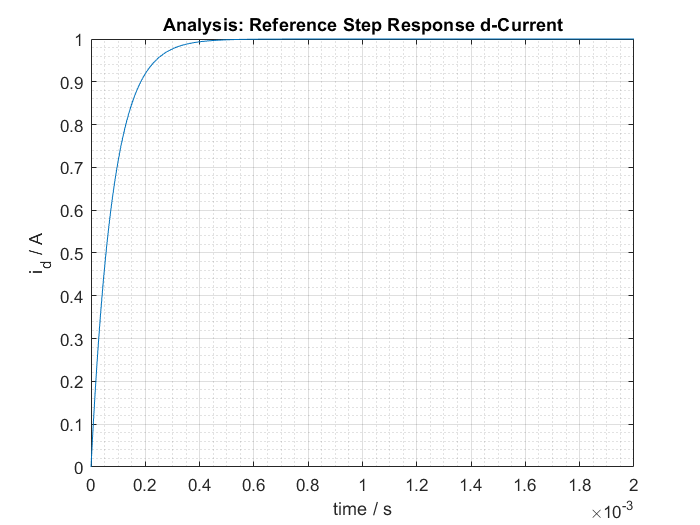

t_plot = 2e-3;

f_w = 2000;
T_w = 1/(2*pi*f_w);

L_d = 25e-6;
R_s = 50e-3;
G_p = tf(1/R_s,[L_d/R_s 1]);

k_p = L_d/T_w;
k_i = R_s/T_w;
G_r = k_p + tf(k_i,[1 0]);

G_w = feedback(G_r*G_p,1);

[data_c, time_c] = step(G_w,t_plot);

figure;
plot(time_c,data_c);
grid on
title('Analysis: Reference Step Response d-Current')
xlabel('time / s')
ylabel('i_d / A')
grid minor 

    
    t_s = 1/20000;

dG_p = c2d(G_p,t_s,'zoh');

dG_r = c2d(G_r,t_s,'foh');
dG_del = tf(1,[1 0],t_s);
[num_d, den_d] = tfdata(dG_r,'v');

dF_o = dG_r*dG_del*dG_p;

dG_w = feedback(dG_r*dG_del*dG_p,1);

[data_d, time_d] = step(dG_w,t_plot);

Bw = bandwidth(dG_w);
Bw = Bw/(2*pi);

disp(Bw)

   4.6199e+03



[Gm,Pm,~,~] = margin(dF_o);
Gm = 20*log10(Gm);
disp(Gm)

    4.0432



disp(Pm)

   35.1019



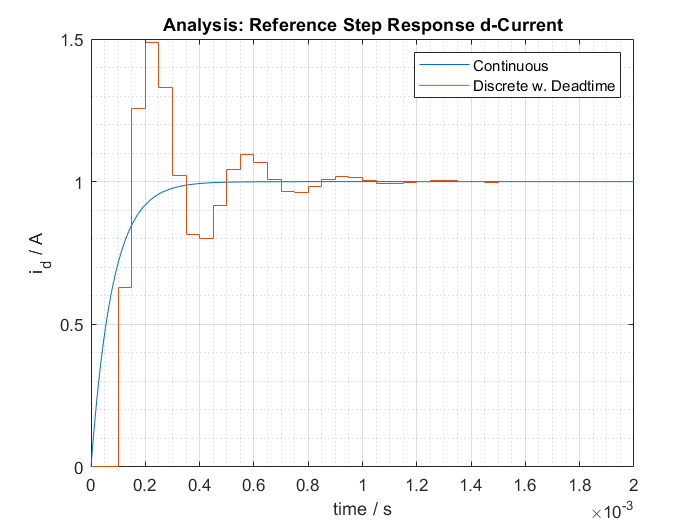




figure;
plot(time_c,data_c);
hold all
stairs(time_d,data_d);
grid on
legend('Continuous','Discrete w. Deadtime')
title('Analysis: Reference Step Response d-Current')
xlabel('time / s')
ylabel('i_d / A')
grid minor 

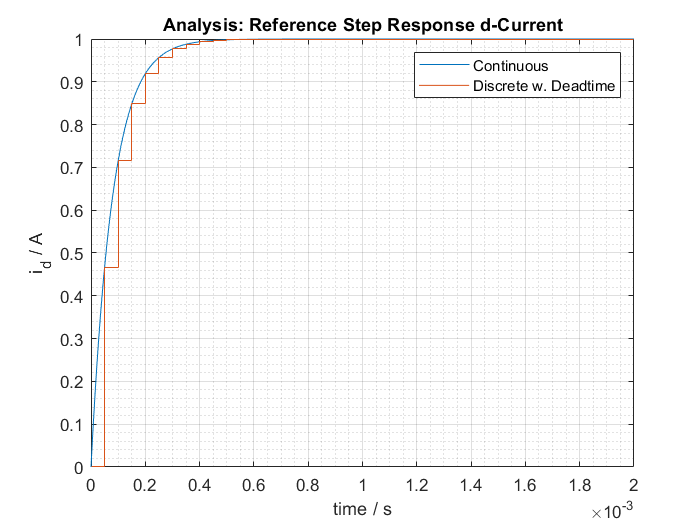

T_plant = L_d/R_s;
K_plant = 1/R_s;
V = 1-exp(-t_s/T_w);
z_p = exp(-t_s/T_plant);
k_p = (V/K_plant)*(z_p/(1-z_p));
k_i = ((exp(t_s/T_plant)-1)/t_s)*k_p;

dG_p = c2d(G_p,t_s,'zoh');

dG_r = ss(1,k_i*t_s,1,k_p+k_i*t_s,t_s);
[num_cos, den_cos] = tfdata(dG_r,'v');

dG_w = feedback(dG_r*dG_p,1);

[data_cos, time_cos] = step(dG_w,t_plot);

figure;
plot(time_c,data_c);
hold all
stairs(time_cos,data_cos);
grid on
legend('Continuous','Discrete w. Deadtime')
title('Analysis: Reference Step Response d-Current')
xlabel('time / s')
ylabel('i_d / A')
grid minor 

figure;
plot(time,i_d_reg,'.','MarkerSize',12);

Unrecognized function or variable 'time'.

hold all
plot(time,i_d_comp,'.','MarkerSize',12);
% stairs(time,i_d_reg);
% hold all
% stairs(time,i_d_comp);
grid on
legend('Conventional','Compensated')
title('Measurement: Reference Step Response d-Current')
xlabel('time / s')
ylabel('i_d / A')
grid minor 